# Homework 4

**Sebastian Aguilera Novoa**

## **1. Unconstrained minimization**

In this exercise we are going to implement different Newton methods to solve the following problem


$$\min_{x, y \in \mathbb{R}} \;\underbrace{\frac{1}{2}(x-1)^2+\frac{1}{2 }\left(10\left(y-x^2\right)\right)^2+\frac{1}{2} y^2}_{=: f(x, y)}$$


Plot the objective function $f(x,y)$ to get an idea of the shape is this.

### Objective Function Plot

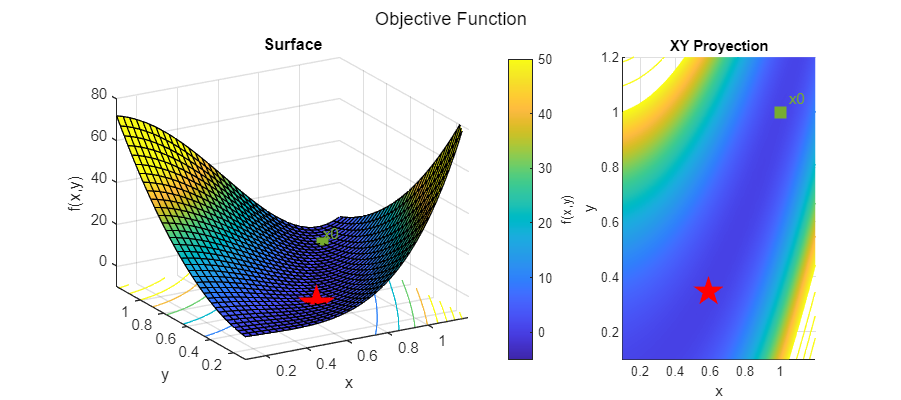

fp1 = @(x,y) 0.5*(x-1).^2 +0.5*(10*(y-x.^2)).^2 + 0.5*y.^2; x1_opt = [0.591077; 0.345913];
FinalPlot(fp1, x1_opt, [1;1], [], 1, [-30 24], "Objective Function", 1) %(f, xstar, x0, xks, flag)

The red point is the global minimum and the pink one is the starting point.

### a) Theorical Gradian and Hessian

First get in papper, the gradient and Hessian matrix of $f(x,y)$. Then, rewrite it in the form $f(x,y) = \frac{1}{2} || R(x,y)||^2_2$ where $R:\mathbb{R}^2 \to \mathbb{R}^3$ is the residual function. Determine the Hessian by the Gauss-Newton method and compare it with the exact. When do the two matrices coincide?

Jacobian


$$\nabla f (x,y)= \Big(x-1+10(y-x^2)(-2x)10,\; 10(y-x^2)10+y \Big)\\
\quad \;  = \Big(x-1-200xy+200x^3, \; -100x^2+101y \Big)
$$


The Hessian

$\nabla^2 f (x,y) = \pmatrix{
\frac{\partial^2 f}{\partial x^2} & \frac{\partial^2 f}{\partial x \partial y} \cr
\frac{\partial^2 f}{\partial y \partial x} & \frac{\partial^2 f}{\partial y^2} } = \pmatrix{
600x^2-200y+1 & -200 x \cr -200x & 101}$                    (1)

but this problem can be formulated as a least saquare problem as follows

#### Least Square Problem


$$\min_{x, y \in \mathbb{R}} \; \frac{1}{2} || R(x,y)||^2_2$$


with the residual vector is


$$R(x,y ) =  \Big( x-1, 10(y-x^2), y\Big)\\
\frac{1}{2} || R(x,y)||^2_2 = \frac{1}{2}    \Big[ (x-1)^2+ (10(y-x^2))^2+y^2\Big]$$


which gives the same problem. Now let's calculate the Jacobian to the new vector field $R$ and then approximate the Hessian by this Jacobian


$$J = \nabla R = \pmatrix{
\frac{\partial R_1}{\partial x} & \frac{\partial R_1}{\partial y} \cr
\frac{\partial R_2}{\partial x} & \frac{\partial R_2}{\partial y} \cr
\frac{\partial R_3}{\partial x} & \frac{\partial R_3}{\partial y} } =
\pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
}$$


Hessian approximantion by Newton Gauss method


$$H_R=J^T J = \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
}^T \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
} = 
\pmatrix{
1 & -20x & 0 \cr
0 & 10 & 1  
} \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
} \approx H\\
H_R\approx  \pmatrix{1 +400x^2 & -200x \cr
-200x & 101}$$


then (1) coincide with the Hessian approximation if and only if 


$$1+400x^2 = 600x^2-200y+1\\
200 y =200x^2\\
y = x^2 $$


then the approximate optimization problem is


$$\min_{x \in \mathbb{R}} \; \frac{1}{2} || R(x,y)||^2_2\\
\quad \text{s.t.} \qquad y =  x^2$$


with


$$R(x) = R\left(x,  x^2 \right) =  \Big( x-1, 10\left( x^2-x^2\right),  x^2 \Big)\\
\frac{1}{2} || R(x)||^2_2 = \frac{1}{2}    \Big[ (x-1)^2+ x^2 \Big] = \frac{1}{2} (2x^2-2x+1)$$


which is equivalent to solve


$$\min_{x \in \mathbb{R}} \;  x^2-x+\frac{1}{2} = g(x)$$


where the solution can be find by solving $g'(x) = 0 = 2x-1$


$$x^* = \frac{1}{2}, \; y^*=g(x^*) = \frac{1}{4}$$


then the optimal point is $(0.5,0.25)$, which is the approximate solution for the approximate optimization problem. 

¿is this a good enough approximation?

#### **Function, Gradients and Hessians**

f        = @(x) 0.5*(x(1)-1)^2 + 0.5*(10*(x(2)-x(1)^2))^2 + 0.5*x(2)^2;
Gradient = @(x) [200*x(1)^3+x(1)-200*x(1)*x(2)-1; -100*x(1)^2+101*x(2)]; % G(x) = H(x,y) 
Hessian  = @(x) [600*x(1)^2+1-200*x(2) -200*x(1); -200*x(1) 101];        % H(x) = H(x,y) 

R         = @(x) [x(1)-1; 10*(x(2)-x(1)^2); x(2)];
JacobianR = @(x) [1 0; -20*x(1) 10; 0 1];
HessianR  = @(x) [1+400*x(1)^2 -200*x(1);-200*x(1) 101];

scale = 1; xtest = [0.5911; 0.3459]; x0 = [1*scale; 1*scale];  

### 0) CasADI

**One way: NLP solver**

import casadi.*

x   = SX.sym('x'); y = SX.sym('y');
nlp = struct('x',[x;y], 'f',0.5*(x-1)^2+0.5*100*(y-x^2)^2+0.5*y^2);
S   = nlpsol('S', 'ipopt', nlp); %disp(S)
r   = S('x0',x0,'lbg',0,'ubg',0);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

x_opt = r.x;
t_casADI_1 = S.stats.t_proc_total;
I_casADI_1 = S.stats.iter_count; %tic(t0);

**Second Way: Default solver**

tstart = tic();
opti  = casadi.Opti();
x_opt = opti.variable(2);

opti.minimize(f(x_opt));

opti.solver('ipopt');
sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

xopt = sol.value(x_opt);
t_casADI_2 = sol.stats.t_proc_total;
I_casADI_2 = sol.stats.iter_count; 

### **00) Matlab**

Using matlab solver to NLP

options = optimoptions('fminunc','Display','iter');%'Algorithm','quasi-newton');
t0 = tic();
[x_M, fval_M, exitflag_M, output] = fminunc(f,x0,options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3             0.25                             1
     1          15         0.247525      0.0049505           0.99  
     2          24        0.0747465             91          0.544  
     3          27      2.25174e-12              1       2.26e-09  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x_M =     1.0000
    1.0000


fval_M = 2.2517e-12

exitflag_M = 1

output = struct with fields:
       iterations: 3
        funcCount: 27
         stepsize: 0.3867
     lssteplength: 1
    firstorderopt: 2.2568e-09
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 1.128374e-09, is less ↵than options.OptimalityTolerance = 1.000000e-06.'


t_matlab = toc(t0);
I_matlab = output.iterations;

### b) Newton Method

Implement your own Newton method using the Hessian and complete steps. Start from the inital value $(x_0,y_0)=(1,1)$ and use it as a stop condition $|| \nabla f (x_k, y_k)||_\infty \geq 10^{-3}$. Keep a track over the iterations $(x_k,y_k)$ and add it to the contour plot.

In order to solve the problem by the Newton step let's remember the Taylor series around $t$, the  descent direction


$$f(x_k+t) \approx f(x_k) + \nabla f (x_k) t + \frac{1}{2} \nabla^2 f (x_k) t^2$$


which has a minimum at


$$\frac{d}{dt} f(x_k+t) = \frac{d}{dt} \left(f(x_k) + \nabla f (x_k) t + \frac{1}{2} \nabla^2 f (x_k) t^2\right) = 0 \\
\nabla f (x_k) +  t = 0\\
t = - \nabla^2 f(x_k) ^{-1} \nabla f (x_k) =  - \nabla^2 f_k ^{-1} \nabla f_k$$


then, the approximation is


$$x_{k+1} = x_k  -  \nabla^2f_k^{-1} \nabla f_k$$


which is the Newton iteration that is programming in the `Iteration` function. 

Newton = @(xk) -Hessian(xk)\Gradient(xk); 
[xk_Newton, c_Newton, time_Newton] = Iteration(x0, Newton, Gradient)

xk_Newton =     1.5000    1.0000
    1.5000    1.0000


c_Newton = 1

time_Newton = 0.0017

FinalPlot(fp1, x1_opt, x0, xk_Newton(:,2:end-1), 1, [-30 24], "Newton Method Steps", 1)

### c) Gauss- Newton Method

Update by adding a Newton type method that uses the Hessian of the Gauss-Newton method instead. Add the resultant iterations$(x_k,y_k)$  to the plot.

In this approximation the updated is made by approximating the Hessian with the Jociban of the residual vector


$$H \approx J^T J = H_R$$


then the iterations is


$$x_{k+1} = x_k  -  H_R^{-1} \nabla f_k$$


%GaussNewtonApprox  = @(xk) -(Gradient(xk)'*Gradient(xk))\ (Gradient(xk));%'*f(xk));
%[xk_GN, c_GN] = Iteration(x0, GaussNewtonR, Gradient)
GaussNewton = @(xk) -HessianR(xk)\Gradient(xk); 
[xk_GN, c_GN, time_GN] = Iteration(x0, GaussNewton, Gradient)
FinalPlot(fp1, x1_opt, x0, xk_GN(:,2:end-1), 1, [-30 24], "Gauss-Newton Method Steps", 1);

### d) Add Regularization

Check how the steepest descent method works in this example. Now the Hessian approximation is $\alpha I$, where $\alpha$ is a positive scalar and $I$ is the identity matrix of appropiate size. What values does the algorithm converge for?

In this case, a regularization term is added to the Hessian,


$$H_{reg} \approx H+\alpha I$$


then the iteration is


$$x_{k+1} = x_k  - H_{reg}^{-1} \nabla f_k = x_k  - (H+\alpha I)^{-1} \nabla f_k$$


- 
$$\alpha=1$$


HessianApprox  = @(xk) -(Hessian(xk)+0.001*eye(size(xk,1)))\Gradient(xk);
%HessianApproxR = @(xk) -(HessianR(xk)+alpha*eye(size(xk,1)))\Gradient(xk);
[xk_reg0, c_reg0, time_reg0] = Iteration(x0, HessianApprox, Gradient)
FinalPlot(fp1, x1_opt, x0, xk_reg0(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=0.001", 1)

- 
$$\alpha=1$$


alpha = 1; HessianApprox  = @(xk) -(Hessian(xk)+alpha*eye(size(xk,1)))\Gradient(xk);
%HessianApproxR = @(xk) -(HessianR(xk)+alpha*eye(size(xk,1)))\Gradient(xk);
[xk_reg1, c_reg1, time_reg1] = Iteration(x0, HessianApprox, Gradient)
FinalPlot(fp1, x1_opt, x0, xk_reg1(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=1", 1)
%[xk_reg_R, c_reg_R, time_reg_R] = Iteration(x0, HessianApproxR, Gradient)
%xk_reg_R(:,end)'
%FinalPlot(fp1, x1_opt, x0, xk_reg_R(:,2:end-1), 1, [-30 24], "Regularization Method Steps with HessianR", 1)

- 
$$\alpha=100$$


HessianApprox  = @(xk) -(Hessian(xk)+100*eye(size(xk,1)))\Gradient(xk);
[xk_reg2, c_reg2, time_reg2] = Iteration(x0, HessianApprox, Gradient)
FinalPlot(fp1, x1_opt, x0, xk_reg2(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=100", 0)

- 
$$\alpha=200$$


HessianApprox  = @(xk) -(Hessian(xk)+200*eye(size(xk,1)))\Gradient(xk);
[xk_reg3, c_reg3, time_reg3] = Iteration(x0, HessianApprox, Gradient)
FinalPlot(fp1, x1_opt, x0, xk_reg3(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=200", 0)

- 
$$\alpha=500$$


HessianApprox  = @(xk) -(Hessian(xk)+500*eye(size(xk,1)))\Gradient(xk);
[xk_reg4, c_reg4, time_reg4] = Iteration(x0, HessianApprox, Gradient)
FinalPlot(fp1, x1_opt, x0, xk_reg4(:,2:end-1), 1, [-30 24], "Regularization Method Steps, α=500", 0)

### e) Methods Performance

Compare the performance of the implemented methods. Consider the iteration path $(x_k,y_k)$, the number of iterations and the execution time. To measure the time, you can use the command `tic `and `toc `from Matlab.

Method  = ["Newton"; "Gauss-Newton"; "Regularization, α=1e-3";"Regularization, α=1"; "Regularization, α=100";
           "Regularization, α=200"; "Regularization, α=500"; "CasADI 1"; "CasADI NLP"; "Matlab"];
Time    = [time_Newton; time_GN; time_reg0; time_reg1; time_reg2; time_reg3; time_reg4; t_casADI_1; t_casADI_2; t_matlab]; 
No_Iter = [c_Newton; c_GN; c_reg0; c_reg1; c_reg2; c_reg3; c_reg4; I_casADI_1; I_casADI_2; I_matlab];
tabla   = sortrows(table(Method, Time, No_Iter),2)

tabla = 10×3 table
             Method               Time       No_Iter
    ________________________    _________    _______

    "Regularization, α=100"     0.0023318       12  
    "Gauss-Newton"              0.0038435       14  
    "Regularization, α=1"       0.0038891        6  
    "Regularization, α=1e-3"    0.0046272        5  
    "Newton"                    0.0057063        5  
    "Regularization, α=200"      0.027701     2736  
    "Matlab"                     0.093627       12  
    "Regularization, α=500"       0.11503     7089  
    "CasADI NLP"                    0.116        8  
    "CasADI 1"                      0.621        8  


When the start point is $(1,1)^T$ and the tolerance is $10^{-8}$, difference between solutions $|x_{k+1}-x_{k}|<\text{tol}$.

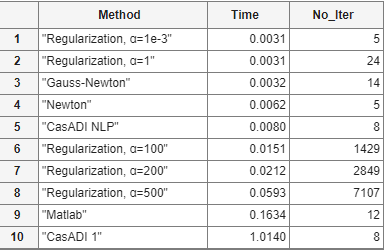

We find that the fatest method is when the regularization term is added, but this may depend on the execution so statical brenchnmarks are suggested, although  it has an execution time similar to the same mehotd but with bigger regularization term 1. In the other hand, the method with less steps is the CasADI NLP which gives 8 iterations in both cases, when the start point is $(1,1)$ and $(100,100)$, after this is the Matlab method and then the Gauss Newton method although when the start point is close to the solution the iterations less for the majority of methods and then the best methods are the Newton and regularization method with $\alpha = 1e-2$.

## 2. Methods Implementation

Since we want to implement some linear search algorithms, the following formulas will be usefull

Armijo Rule: $$f\left(x_k+\alpha p_k\right) \leq f\left(x_k\right)+c_1 \alpha \nabla f_k^T p_k$,$

Iteration formula: $x_{k+1} = x_k+ \alpha_k p_k$

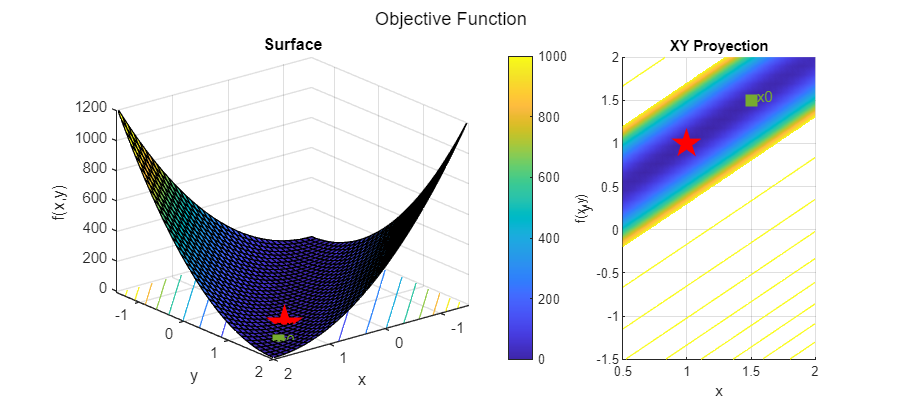

fp2 = @(x,y) 100*(y-x)^2 + (1-x)^2; x2_opt = [1; 1];
FinalPlot(fp2, x2_opt, [1.5;1.5], [], 0, [-218.8 25.2], "Objective Function", 1); %(f, xstar, x0, xks, flag)

### 0) Comparison

Using each of the previous methods solve


$$\underset{x_1,x_2\in \mathbb{R}}{min} \quad \underbrace{100 (x_2-x_1)^2 +(1-x_1)^2}_{=f(x_1,x_2)}$$



$$f(x_1, x_2) = || R(x_1, x_2)||\\
R(x_1, x_2) = \big(10(x_2-x_1), 1-x_1\big)$$


Take as initial value $(1.5, 1.5)^T$, the optimum value is $(1,1)$. The algorithm output have to show a table with the following information


$$k \qquad x_k \qquad  f(x_k) \qquad \nabla f(x_k)  \qquad  p_k  \qquad  t^*$$


Compare the methods performance.

#### **Gradient and Hessian **


$$\nabla f= \big(-(2)100(x_2-x_1) -2 (1-x_1), (2)100(x_2-x_1)\big)\\
\nabla f= \big(200(x_1-x_2) -2 +2x_1, \;200(x_2-x_1)\big)\\
\nabla^2 f (x,y) = \pmatrix{
200+2 & -200 \cr -200  & 200} = \pmatrix{
202 & -200 \cr -200  & 200} $$


#### Rules to $\alpha$

global c1 c2 alpha0 rho

global Armijo Wolfe StrongWolfe % Goldstein

f        = @(x) 100*(x(2)-x(1))^2 + (1-x(1))^2;
Gradient = @(x) [200*(x(1)-x(2))-2+2*x(1); 200*(x(2)-x(1))]; % G(x) = H(x,y) 
Hessian  = @(x) [202 -200; -200 200];        % H(x) = H(x,y) 

Armijo      = @(xk, f, Gradient, pk, alphak) f(xk+alphak*pk) <= f(xk)+c1*alphak*Gradient(xk)'*pk;
Wolfe       = @(xk, f, Gradient, pk, alphak) (Gradient(xk+alphak*pk)'*pk >= c2 * Gradient(xk)'* pk)*Armijo(xk, f, Gradient, pk, alphak);
StrongWolfe = @(xk, f, Gradient, pk, alphak) (norm(Gradient(xk+alphak*pk)'*pk,2) >= c2 * norm(Gradient(xk)'* pk,2))*Armijo(xk, f, Gradient, pk, alphak);
%Goldstein   = @(xk, f, Gradient, pk, alphak) f(xk)+(1-c)*alphak*Gradient(xk)'*pk <= f(xk)+c*alphak*Gradient(xk)'*pk;   

c1 = 1e-4; c2 = 0.9; alpha0 = 1; rho=1/2; %c1 = 1e-4 sa
x0 = [scale*1.5; scale*1.5];

### 00) Solution by Matlab

This problem can be write as a quadratic problem as follows


$$R = \pmatrix{-10 & 10 \cr -1 & 0} \pmatrix{x_1 \cr x_2}+\pmatrix{0 \cr 1} = Ax+b\\
R^T = x^TA^T +b^T\\
f = ||R|| = R^TR = (x^TA^T +b^T) (Ax+b)= x^TA^TAx+2b^TAx+b^Tb\\
f = \frac{1}{2} x^THx+g^Tx\\
H = 2 A^TA, \quad g^T = 2b^TA, \quad b^Tb=1$$


then the problem can be formulated as, omiting the constant part


$$\underset{x\in \mathbb{R}^2}{min} \quad  \frac{1}{2} x^THx+g^Tx$$


where $H = 2 A^TA$ and $g^T = 2b^TA$.

options = optimoptions('quadprog','Display','iter');
A = [-10 10; -1 0]; b = [0; 1];
H = 2*(A')*A;  g = 2*A'*b;
tStart = tic();
[x,fval,exitflag,output,lambda] = quadprog(H,g,[],[],[],[],[],[],[150; 30],options)

The interior-point-convex algorithm does not accept an initial point.
Ignoring X0.

 Iter            Fval  Primal Infeas    Dual Infeas  Complementarity  
    0   -1.000000e+00   0.000000e+00   9.999999e-08     0.000000e+00  
    1   -1.000000e+00   0.000000e+00   5.002221e-11     0.000000e+00  

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

x =     1.0000
    1.0000


fval = -1.0000

exitflag = 1

output = struct with fields:
            message: 'Minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative dual feasibility, 2.476347e-13,↵is less than options.OptimalityTolerance = 1.000000e-08, the complementarity measure,↵0.000000e+00, is less than options.OptimalityTolerance, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-08.'
          algorithm: 'interior-point-convex'
      firstorderopt: 5.0022e-11
    constrviolation: 0
         iterations: 1
       linearsolver: 'dense'
       cgiterations: []


lambda = struct with fields:
    ineqlin: [0×1 double]
      eqlin: [0×1 double]
      lower: [2×1 double]
      upper: [2×1 double]


tstar_Matlab = toc(tStart);

### 000) CasADI - ipopt solver

tstart = tic();
opti  = casadi.Opti();
x_opt = opti.variable(2);

opti.minimize(0.5*x_opt'*H*x_opt+g'*x_opt);

opti.solver('ipopt');
sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

xopt = sol.value(x_opt);
tstart_casADI = toc(tstart);

### 000) CasADI II - Quadratic Problem solver

import casadi.*
tstart = tic();

x = SX.sym('x'); y = SX.sym('y');
qp = struct('x',[x;y], 'f',100*(y-x)^2+(1-x)^2);
S = qpsol('S', 'qpoases', qp);

r = S('lbg',0);



#################   qpOASES  --  QP NO.   1   ##################

    Iter   |    StepLength    |       Info       |   nFX    
 ----------+------------------+------------------+--------- 
       0   |   0.000000e+000   |   REM BND    1   |     1   
       1   |   1.666665e-007   |   REM BND    0   |     0   
       2   |   1.000000e+000   |    QP SOLVED     |     0   


x_opt = r.x

x_opt = [1, 1]

tstart_casADI2 = toc(tstart);

### a) Steepest Descent

Such that employs the backward globalization technique with Armijo rule.

In this case the search direction is the gradient of the function at the corresponding point


$$p_k = \nabla f_k$$


pk_func_SD = @(xk) -Gradient(xk);
[ks_SD, xks_SD, fks_SD, grad_SD, pks_SD, tstar_SD, I_SD] = MethodImpl(pk_func_SD, x0, Gradient, f, Armijo);
Tabla(xks_SD, ks_SD, grad_SD, pks_SD, fks_SD)

ans = 1324×8 table
    k       x         y          f        Grad_x       Grad_y       pk_x        pk_y  
    __    ______    ______    _______    _________    ________    ________    ________

     1       1.5       1.5       0.25            1           0          -1           0
     2    1.4922       1.5    0.24835     -0.57812      1.5625     0.57812     -1.5625
     3    1.4933    1.4969    0.24468      0.26031     0.72632    -0.26031    -0.72632
     4    1.4892    1.4856     0.2407       1.7084    -0.72994     -1.7084     0.72994
     5    1.4859     1.487    0.23623      0.74927     0.22255    -0.74927    -0.22255
     6    1.4742    1.4835     0.2336     -0.92015      1.8686     0.92015     -1.8686
     7     1

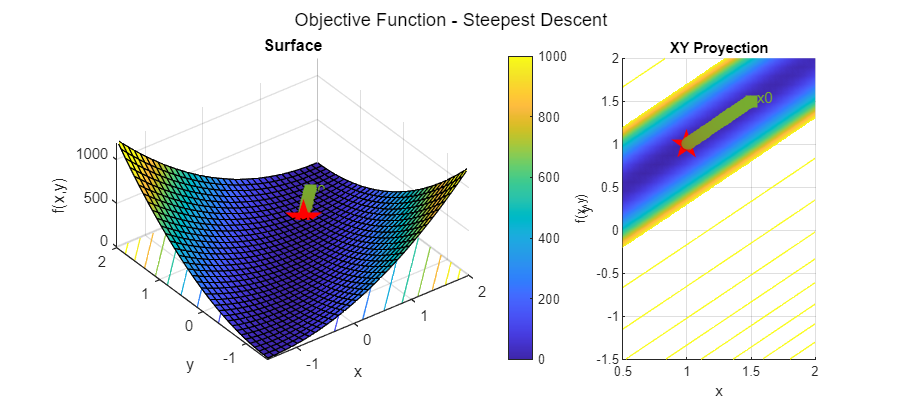

FinalPlot(fp2, x2_opt, x0, xks_SD(:,2:end-1), 0, [-37 53], "Objective Function - Steepest Descent", 0)

### b) Newton 

Such that employs the backward globalization technique with Armijo rule.

In this case the search direction is the product of the inverse Hessian with the gradient of the function at the corresponding point


$$p_k^N = -(\nabla^2 f_k)^{-1}\nabla f_k$$


pk_func_Newton = @(xk) -Hessian(xk)\Gradient(xk);
[ks_N, xks_N, fks_N, grad_N, pks_N, tstar_N, I_N] = MethodImpl(pk_func_Newton, x0, Gradient, f, Armijo);
Tabla(xks_N, ks_N, grad_N, pks_N, fks_N)

ans = 3×8 table
    k     x      y         f          Grad_x      Grad_y       pk_x           pk_y    
    _    ___    ___    __________    _________    ______    ___________    ___________

    1    1.5    1.5          0.25            1      0              -0.5           -0.5
    2      1      1    3.5942e-29    1.199e-14      0       -5.9952e-15    -5.9952e-15
    3      1      1             0            0      0                 0              0


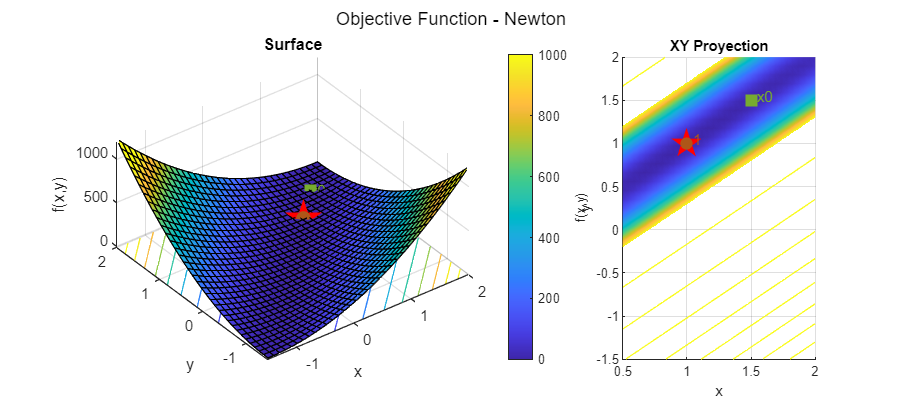

FinalPlot(fp2, x2_opt, x0, xks_N(:,2:end-1), 0, [-37 53], "Objective Function - Newton", 1)

### c) Quasi-Newton BFGS

Such that employs the backward globalization technique with Armijo rule

In this case the search direction is the product of the inverse approximate Hessian ($B_k$) with the gradient of the function at the corresponding point, in this case the Hessian approximation is calculated each iterations as follows


$$s_k = x_{k+1}-x_k, \qquad y_k = \nabla f_{k+1} - \nabla f_k, \qquad B_{k+1} s_k = y_k$$



$$B_{k+1} = B_k - \frac{B_k s_k s_k^T B_k}{s_k^T B_k s_k} + \frac{y_k y_k^T}{y_k^T y_k}$$


then the search direction is


$$p_k = -B_k^{-1}\nabla f_k$$


[ks_BFGS, xks_BFGS, fks_BFGS, grad_BFGS, pks_BFGS, tstar_BFGS, I_BFGS] = MethodBFGS(x0, Gradient, f, Armijo);
Tabla(xks_BFGS, ks_BFGS, grad_BFGS, pks_BFGS, fks_BFGS)

ans = 25×8 table
    k        x          y           f           Grad_x         Grad_y         pk_x          pk_y   
    __    _______    _______    __________    ___________    __________    __________    __________

     1        1.5        1.5          0.25              1             0            -1             0
     2     1.4922        1.5       0.24835       -0.57812        1.5625       0.57812       -1.5625
     3     1.4933     1.4969       0.24468        0.26031       0.72632       -1.4898      -0.98406
     4     1.4468     1.4662       0.23737        -2.9938        3.8873       0.12968       -7.1763
     5      1.447     1.4522       0.20249       -0.13936        1.0334       -21.062        -18.65
     6    

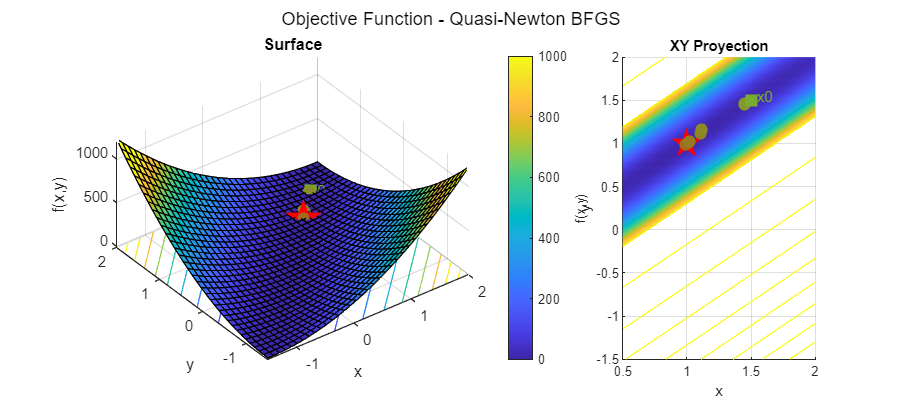

FinalPlot(fp2, x2_opt, x0, xks_BFGS(:,2:end-1), 0, [-37 53], "Objective Function - Quasi-Newton BFGS",0)

### d) Newton Dogleg Trust Region

Such that employs the backward globalization technique with the Dogleg trust region. 


$$\underset{x\in \mathbb{R}^2}{min} \quad  f^T +g^Tx+ \frac{1}{2} x^THx$$


First, let's verify that the matrix $H$ is positive defined by checking its eigenvalues

eig(H)'

ans =     0.9975  401.0025


here you can see that both eigenvalues are nonzero positive numbers, then the matrix $H$ is positive defined. First we test the `NewtonTrustRegion function `with 10000 iterations and then we solve again the problem but using the correct number of iterations for some tolerance.

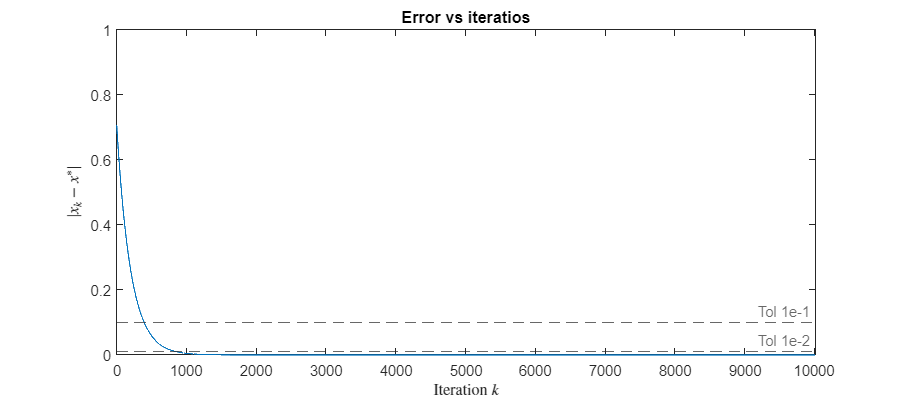

[xks_NDTR,time_NDTR, Ies, fks_NDTR, grad_NDTR, pks_NDTR] = NewtonTrustRegion(10000, x0, f, Gradient, Hessian);
clf;
figure('Position', [10 10 900 400])
plot(1:10000+1, Ies)
yline(1e-1, '--', Label='Tol 1e-1'); yline(1e-2, '--', Label='Tol 1e-2');
ylabel("$|x_{k}-x^*|$",Interpreter="latex")
xlabel("Iteration $k$",Interpreter="latex")
xlim([0 10010]); ylim([0 1]) 
title("Error vs iteratios")

tol1_ind = find(Ies < 1e-1); tol1_ind = tol1_ind(1);
tol2_ind = find(Ies < 1e-3); tol2_ind = tol2_ind(1);
tol3_ind = find(Ies < 1e-8); tol3_ind = tol3_ind(1);
disp(['Required iteratios to get a tolerance of 1e-1 ' num2str(tol1_ind) newline...
      'Required iteratios to get a tolerance of 1e-3 ' num2str(tol2_ind) newline ...
      'Required iteratios to get a tolerance of 1e-8 ' num2str(tol3_ind)])

Required iteratios to get a tolerance of 1e-1 395
Required iteratios to get a tolerance of 1e-3 1320
Required iteratios to get a tolerance of 1e-8 3634


Implementing the method to get a tolerance of $1e-8$.

[xks_NDTR,time_NDTR, Ies, ks_NDTR, fks_NDTR, grad_NDTR, pks_NDTR] = NewtonTrustRegion(tol3_ind, x0, f, Gradient, Hessian);
T_NDTR = Tabla(xks_NDTR, ks_NDTR, grad_NDTR, pks_NDTR, fks_NDTR)

T_NDTR = 3635×8 table
    k       x         y          f         Grad_x       Grad_y        pk_x           pk_y   
    __    ______    ______    _______    ___________    _______    ___________    __________

     1       1.5       1.5       0.25              1          0           -0.5             0
     2     1.495       1.5    0.24752    -8.8818e-16     0.9901     -0.0049505             0
     3     1.495     1.495    0.24507         0.9901          0     4.4409e-18    -0.0049505
     4    1.4901     1.495    0.24265     -4.885e-15     0.9803     -0.0049015             0
     5    1.4901    1.4901    0.24025         0.9803          0     2.4425e-17    -0.0049015
     6    1.4853    1.4901    0.23787     3.1086e-15  

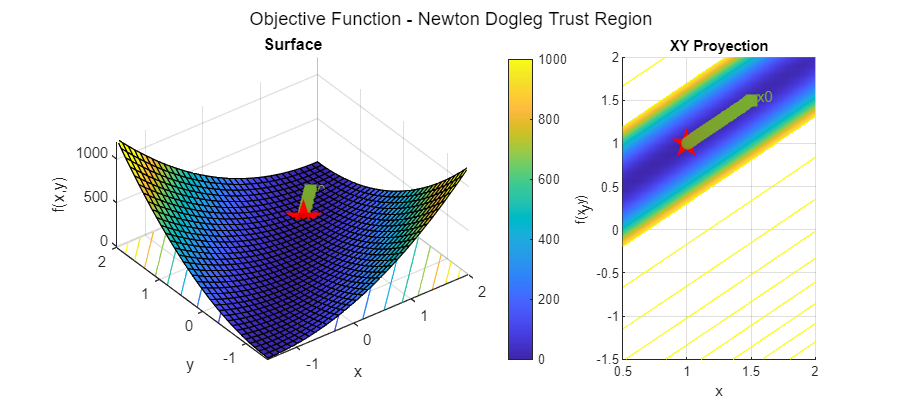

FinalPlot(fp2, x2_opt, x0, xks_NDTR(:,2:end-1), 0, [-37 53], "Objective Function - Newton Dogleg Trust Region",0)

Method  = ["Steepest Descent"; "Newton"; "BFGS"; "Newton Trust Region"; "Matlab-quadprog"; "CasADI"];% "Newton Trust Dogleg"];

Time    = [tstar_SD; tstar_N; tstar_BFGS; time_NDTR; tstar_Matlab; tstart_casADI];
No_Tter = [I_SD; I_N; I_BFGS; tol3_ind; output.iterations; sol.stats.iter_count];
sortrows(table(Method, Time, No_Tter),2)

ans = 6×3 table
           Method              Time       No_Tter
    _____________________    _________    _______

    "Newton"                 0.0042842        2  
    "BFGS"                   0.0098395       24  
    "Matlab-quadprog"         0.068806        1  
    "Steepest Descent"        0.084633     1323  
    "Newton Trust Region"     0.095102     3634  
    "CasADI"                    6.1323        1  


When the start point is $(1.5,1.5)$ and the tolerance is 1e-8, difference between solutions $|x_{k+1}-x_{k}|<\text{tol}$.

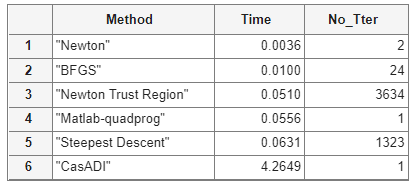

Here we find that the best methods, for both initial points, are the matlab and CasADI methods since the arrive to the solution in one step but the execution time is not te best. The fatest method is the Newton method and then the quasi-Newton BFGS method but grater number of iterations. 

Comparing the results, the most efficient mehotd is the Newton method that is the fastest and arrive to the solution in two steps no matter the starting point.

## Auxiliar Functions

### Methods Implementation

function alphak = Backtracking(xk, f, Gradient, pk, Rule)
    global alpha0 rho
    alpha = alpha0;  %c = 0;
    while not(Rule(xk, f, Gradient, pk, alpha)) %&& c<100
        alpha = rho*alpha; %c = c+1;
    end
    alphak = alpha; %display(c)
end

function [Ks, Xks, Fks, Grad, Pks, tstar, I] = MethodBFGS(x0, Gradient, f, Armijo)
    tstart = tic;
    IterMax   = 2000; tol = 1e-8;
    Bk        = eye(2);
    ks        = [1];
    Gradients = [Gradient(x0)];
    pks       = [-Bk\Gradient(x0)];
    xks       = [x0];
    fks       = [f(x0)];
    
    
    for i=2:IterMax
        alphak = Backtracking(xks(:,end)', f, Gradient, pks(:,end), Armijo);
        
        xks       = [xks xks(:,end)+alphak*pks(:,end)];
        Gradients = [Gradients Gradient(xks(:,end))];
        pks       = [pks -Bk\Gradient(xks(:,end))];
        fks       = [fks f(xks(:,end))];
        ks        = [ks i];
        
        sk = xks(:,end) - xks(:,end-1);
        yk = Gradient(xks(:,end)) - Gradient(xks(:,end-1));
        Bk = Bk - (Bk*(sk*sk')*Bk')/(sk'*Bk*sk)+(yk*yk')/(yk'*yk);

        if norm(xks(:,end)-xks(:,end-1),2) < tol 
            break
        end
    end
    Ks = ks;   Xks = xks; Pks = pks;
    Fks = fks; Grad = Gradients;
    tstar = toc(tstart); I = i-1;
    %display(tstar);
end


function [Ks, Xks, Fks, Grad, Pks, tstar, I] = MethodImpl(pk_func, x0, Gradient, f, Armijo)
    tstart = tic;
    IterMax   = 2000; tol = 1e-8;
    ks        = [1];
    Gradients = [Gradient(x0)];
    pks       = [pk_func(x0)];
    xks       = [x0];
    fks       = [f(x0)];
    
    for i=2:IterMax
        alphak = Backtracking(xks(:,end)', f, Gradient, pks(:,end), Armijo);
        xks    = [xks xks(:,end)+alphak*pks(:,end)];
        
        Gradients = [Gradients Gradient(xks(:,end))];
        pks       = [pks pk_func(xks(:,end))];
        fks       = [fks f(xks(:,end))];
        ks        = [ks i];
        
        if norm(xks(:,end)-xks(:,end-1),2) < tol 
            break
        end
    end
    Ks = ks;   Xks = xks; Pks = pks;
    Fks = fks; Grad = Gradients;
    tstar = toc(tstart); I = i-1;
    %display(tstar);
end

function [xk,c,time] = Iteration(x0, func, Gradient)
    tStart = tic;
    xk = [x0]; tol = 1e-8; %MaxIter = 500; c = 0; 
    while norm(Gradient(xk(:,end)), "inf")  >= tol % && (c < MaxIter)
        xk = [xk xk(:,end)+func(xk(:,end))];
    end
    c = size(xk,2)-1;
    time = toc(tStart);
end

function [xks, time, Ies, Ks, Fks, Grad, Pks] = NewtonTrustRegion(N, x0, f, Gradient, Hessian)
    tstart  = tic;
    DeltaUp = 1; eta = 1/6; % eta [0, 1/4), DeltaUp = DeltaMoño > 0
    Delta0  = DeltaUp/2;    % Deltak (0, DeltaUp)
    Deltak  = Delta0; 
    xks     = [x0]; 

    Grad  = [Gradient(x0)];
    Pks   = [-Deltak*Gradient(xks(:,end))/norm(Gradient(xks(:,end)),2)];
    Fks   = [f(xks(:,end))];
    Ks    = [1];
    
    m    = @(p, xk) f(xk) + Gradient(xk)'*p + 0.5*p'*Hessian(xk)*p;
    
    for k=1:N
    gk = Gradient(xks(:,end));  Bk = Hessian(xks(:,end));
    if gk'*Bk*gk <=0  tauk = 1;
    else              tauk = min(norm(gk,2)^3/(Deltak*gk'*Bk*gk),1);
    end
    pk   = -tauk*Deltak*gk/norm(gk,2); %pkc
    rhok = (f(xks(:,end))-f(xks(:,end)+pk)) / (m(zeros(2,1),xks(:,end))-m(pk,xks(:,end)));
    if rhok < 0.25        Deltak = 0.25*Deltak;
    else
        if (rhok > 0.75) && (norm(pk,2)==Deltak)    Deltak = min(2*Deltak, DeltaUp);
        else                                        Deltak = Deltak;
        end
    end
    if rhok > eta   xks = [xks xks(:,end)+pk];
    else            xks = [xks xks(:,end)];
    end
    Grad = [Grad Gradient(xks(:,end))];
    Pks  = [Pks pk];
    Fks  = [Fks f(xks(:,end))];
    Ks   = [Ks k+1];
    end
    time = toc(tstart);
    Diff = xks-ones(2,N+1);
    Ies  = zeros(1,N);
    for i=1:N+1  Ies(i) = norm(Diff(:,i),2); end    
end

function T=Tabla(xks, ks, grad, pks, fks)
    k  = ks'; f = fks';
    x  = xks(1,:)'; y = xks(2,:)';
    Grad_x = grad(1,:)'; Grad_y = grad(2,:)';
    pk_x = pks(1,:)'; pk_y = pks(2,:)';
    T = table(k,x,y,f,Grad_x,Grad_y,pk_x,pk_y);
end

### Plot Functions

function PlotF3d(f, xstar, x0, xks, flag, viewed, titulo, ax, flagtext)
    %figure();%'Position', [10 10 900 400]); %clf(); 
    if flag==1
        xlim([0.1 1.2]); ylim([0.1 1.2]); zlim([-10 80]); clim([-5 50]); 
        interval = [-0.5 1.2 -0.5 1.2]; 
    else
        xlim([-1.5 2]); ylim([-1.5 2]); zlim([-10 1200]); clim([0 1000]); 
        interval = [-1.5 2 -1.5 2]; 
    end

    hold on
    fsurf(ax, f, interval,'ShowContours','on');
    plot3(ax, xstar(1),xstar(2),f(xstar(1), xstar(2)), 'p', MarkerSize=25, MarkerFaceColor="red", Color="red")
    plot3(ax, x0(1), x0(2), f(x0(1), x0(2)), 'square', MarkerSize=10, MarkerFaceColor=[0.4660 0.6740 0.1880], Color=[0.4660 0.6740 0.1880])
    text(ax, x0(1), x0(2), f(x0(1), x0(2))+5, 'x0', Color=[0.4660 0.6740 0.1880])
    c = colorbar;  c.Label.String='f(x,y)';  
    left_color = [0.4660 0.6740 0.1880];  right_color = [0.9 0 0]; % color according to the attached image
    cmap = interp1([0, 1], [left_color; right_color], linspace(0, 1, size(xks,2)+2));
    cmap = cmap(2:end-1,:);
    %text(xstar(1),xstar(2),f(xstar(1), xstar(2))+10, "goal", Color="red")
    if flagtext==1
    for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i)), '.', MarkerSize=30, Color=cmap(i,:)); %[1 0 1]/i
        text(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i))+5,num2str(i), Color=cmap(i,:))
    end
    else
       for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i)), '.', MarkerSize=25, Color=cmap(i,:)); %[1 0 1]/i
       end
    end
    hold off
    
    grid on
    xlabel('x');   ylabel('y');    zlabel('f(x,y)'); 
    view(viewed); title(titulo); 
end

function PlotF2d(f, xstar, x0, xks, flag, viewed, titulo, ax, flagtext)
    %figure();%'Position', [10 10 900 400]); %clf(); 
    if flag==1
        xlim([0.1 1.2]); ylim([0.1 1.2]); zlim([-10 50]); clim([-5 50]); 
        interval = [-0.5 1.2 -0.5 1.2]; 
    else
        xlim([0.5 2]); ylim([-1.5 2]); zlim([-10 50]); clim([0 50]); 
        interval = [-1.5 2 -1.5 2]; 
    end

    hold on
    fsurf(ax, f, interval,'ShowContours','on', "EdgeColor",'none','AmbientStrength', 0.2);
    plot3(ax, xstar(1),xstar(2),f(xstar(1), xstar(2))+10, 'p', MarkerSize=20, MarkerFaceColor="red", Color="red")
    plot3(ax, x0(1), x0(2), f(x0(1), x0(2))+10, 'square', MarkerSize=10, MarkerFaceColor=[0.4660 0.6740 0.1880], Color=[0.4660 0.6740 0.1880])
    text(ax, x0(1)+0.05, x0(2)+0.05, f(x0(1), x0(2))+10, 'x0', Color=[0.4660 0.6740 0.1880])
    %text(xstar(1),xstar(2),f(xstar(1), xstar(2))+10, "goal", Color="red")
    left_color = [0.4660 0.6740 0.1880];  right_color = [0.9 0 0]; % color according to the attached image
    cmap = interp1([0, 1], [left_color; right_color], linspace(0, 1, size(xks,2)+2));
    cmap = cmap(2:end-1,:);

    if flagtext==1
    for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i))+10, '.', MarkerSize=25, Color=cmap(i,:)); %
        text(ax, xks(1,i)+0.05,xks(2,i)+0.05,f(xks(1,i), xks(2,i))+10,num2str(i), Color=cmap(i,:))
    end
    else 
    for i=1:size(xks,2)
        plot3(ax, xks(1,i),xks(2,i),f(xks(1,i), xks(2,i))+10, '.', MarkerSize=25, Color=cmap(i,:)); %[1 0 1]/i
    end
    end
    hold off
    
    grid on
    xlabel('x');   ylabel('y');    zlabel('f(x,y)'); 
    view(viewed); title(titulo); 
end




function FinalPlot(f, xstar, x0, xks, flag, viewed, titulo, flagtext)
    clf(); 
    h = figure('Position', [10 10 900 400]);

    subplot(1,3,[1:2]);
    ax1 = gca;

    PlotF3d(f, xstar, x0, xks, flag, viewed, "Surface", ax1, flagtext)
   
    subplot(1,3,3);
    ax2 = gca;
    PlotF2d(f, xstar, x0, xks, flag, [0 90], "XY Proyection", ax2, flagtext)
    
    sgtitle(titulo)
end